# Speech Encryption and Decryption

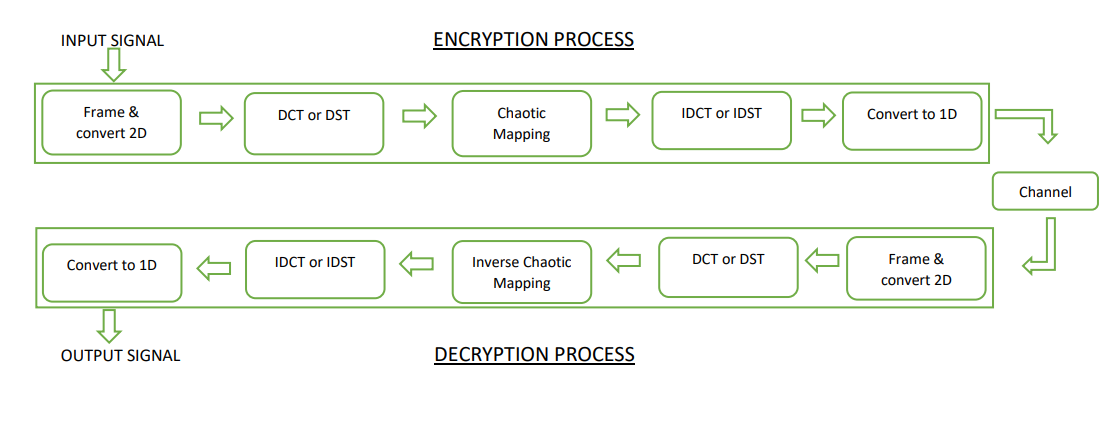

References:

Speech Encryption Using Two Dimensional Chaotic Maps - D Alzharaa Mostafa *, Naglaa. F. Soliman *, Mohamoud Abdalluh* Fathi E. Abd EI-samieD

## **Code:**

close all; clc; clear all;

files = dir(fullfile('C:\Users\Amrut Biju\Desktop\Study\6th Semester\SP\Project\Code\TIMIT\TRAIN\DR8\FCLT0\', '*.wav'));
L = length(files);
waves = {};
for i=1:L
    file=files(i).name;
    filepath = fullfile( 'C:\Users\Amrut Biju\Desktop\Study\6th Semester\SP\Project\Code\TIMIT\TRAIN\DR8\FCLT0\', file );
    waves{end+1} = filepath;
end

audio sample number : 1

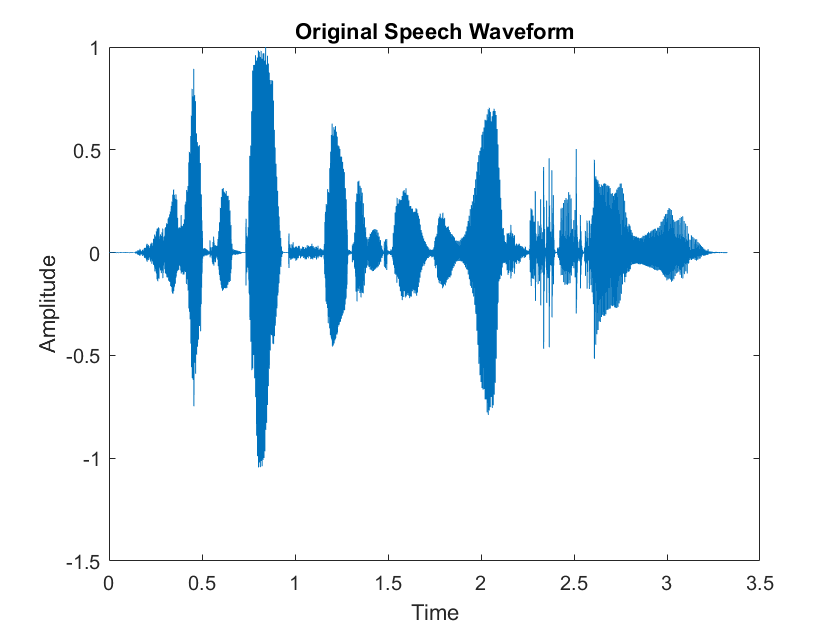

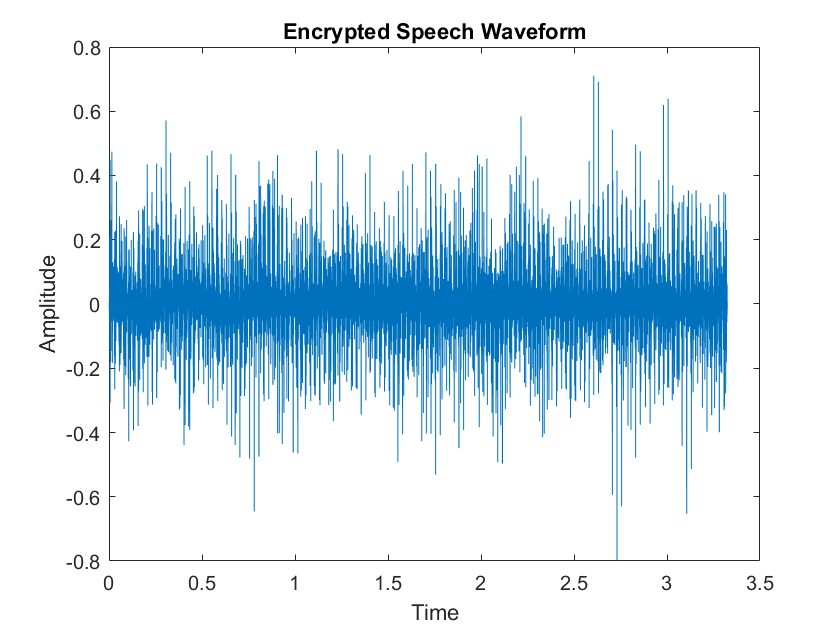

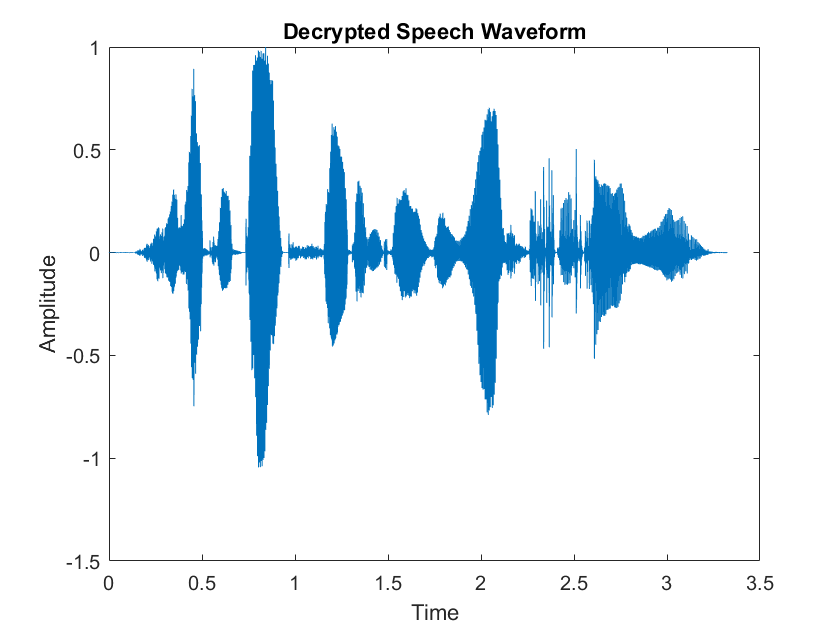

audio sample number : 2

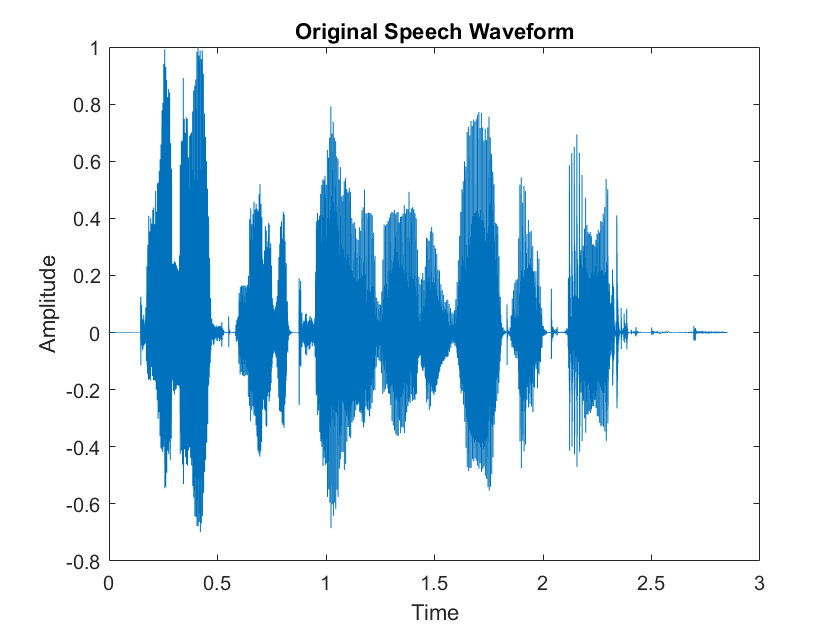

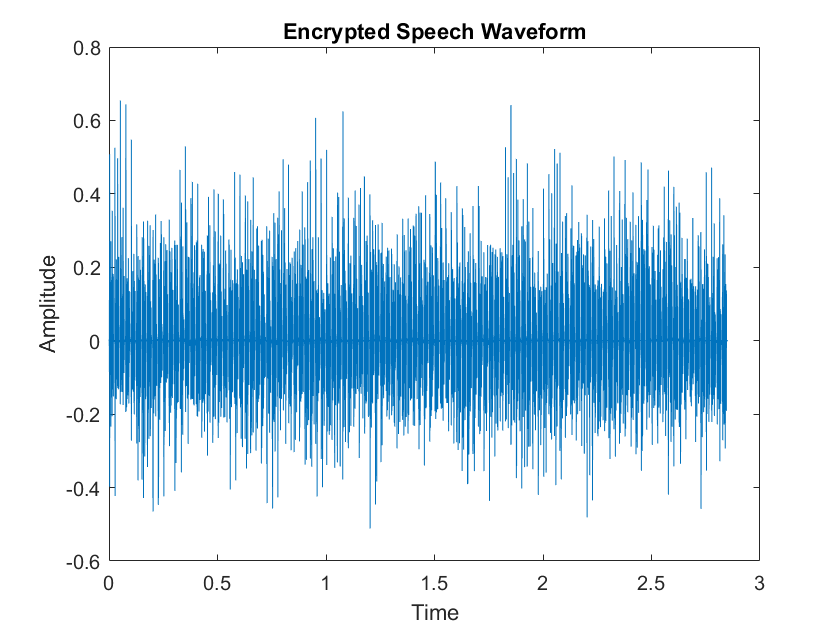

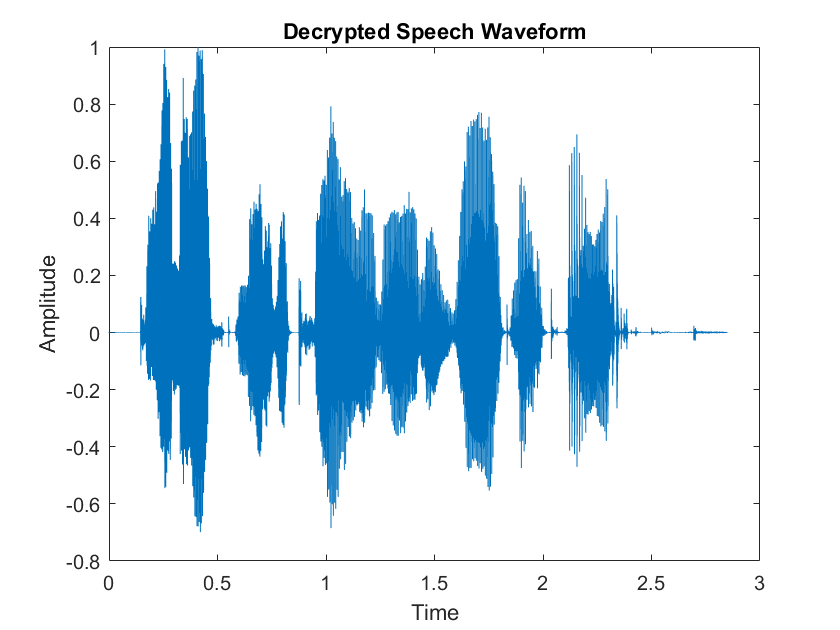

audio sample number : 3

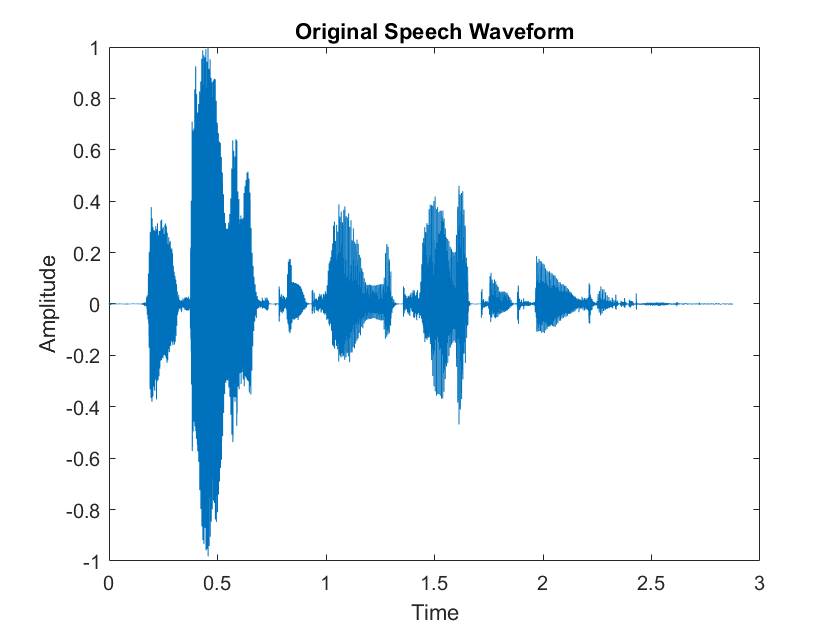

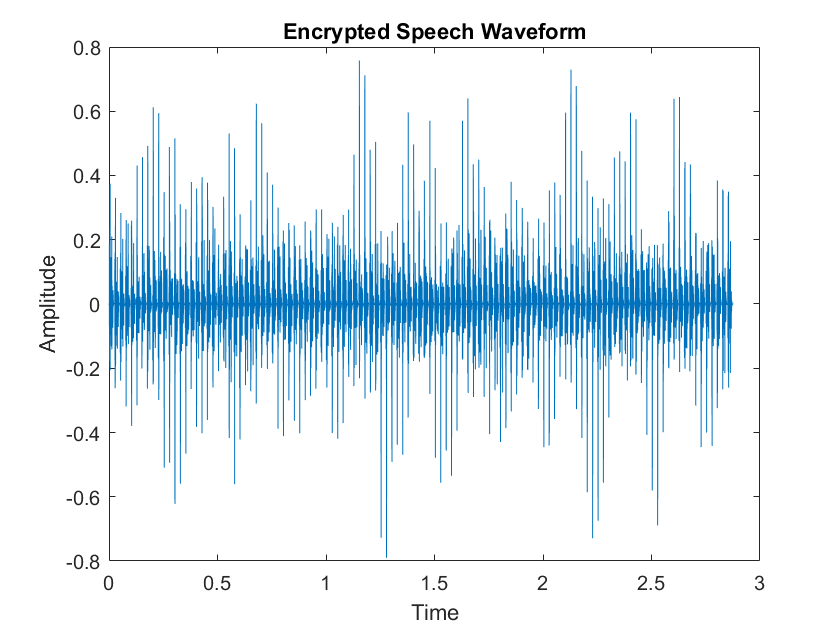

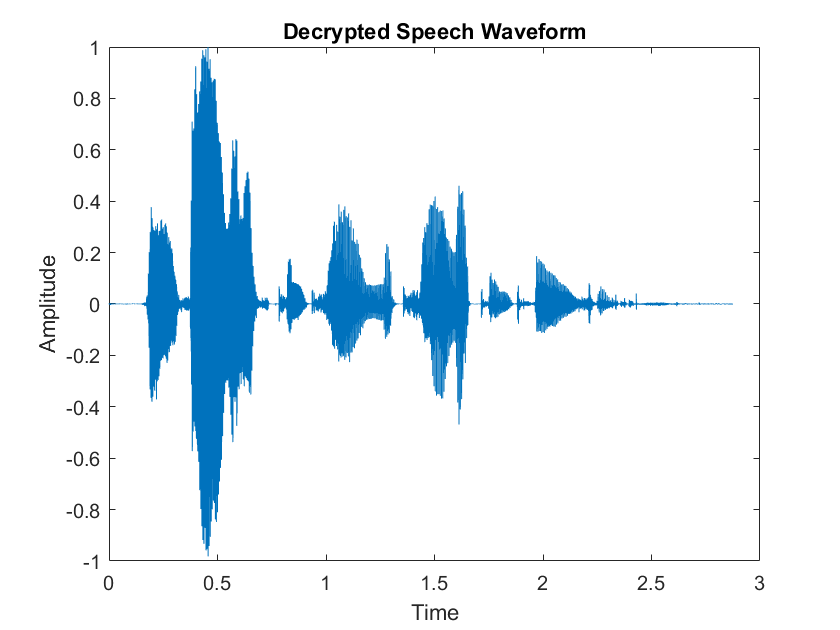

audio sample number : 4

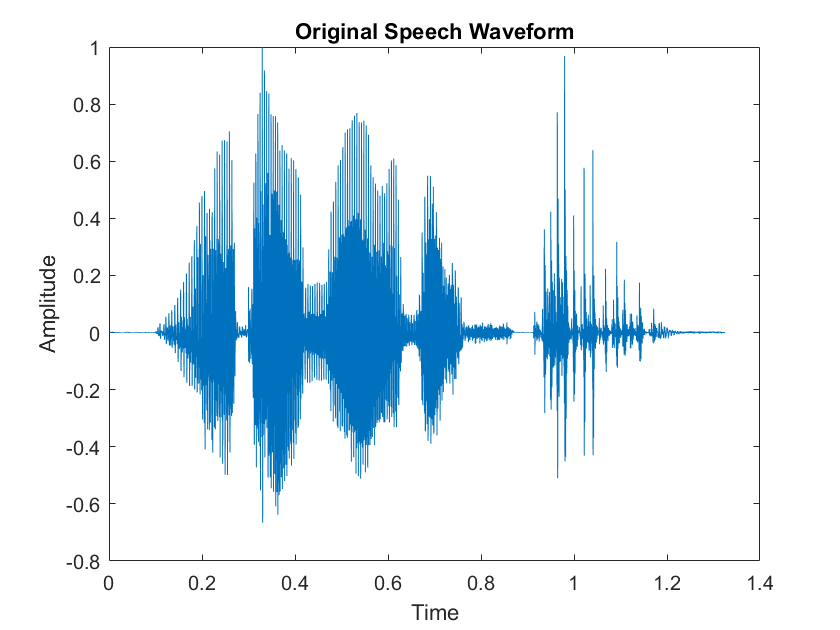

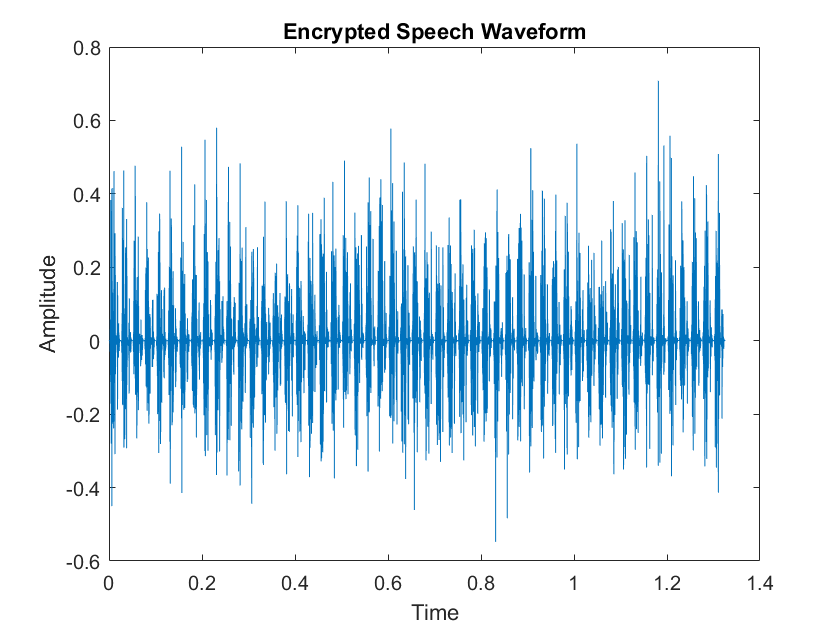

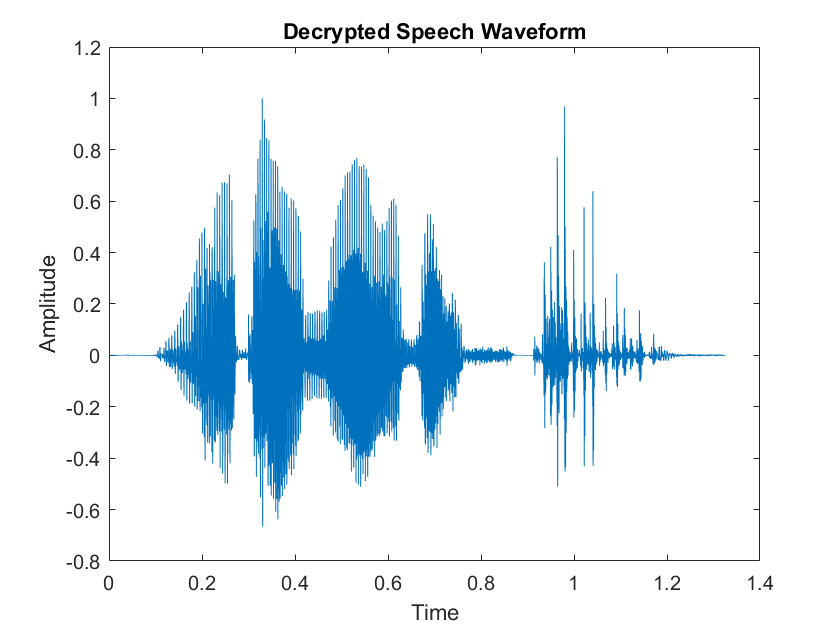

audio sample number : 5

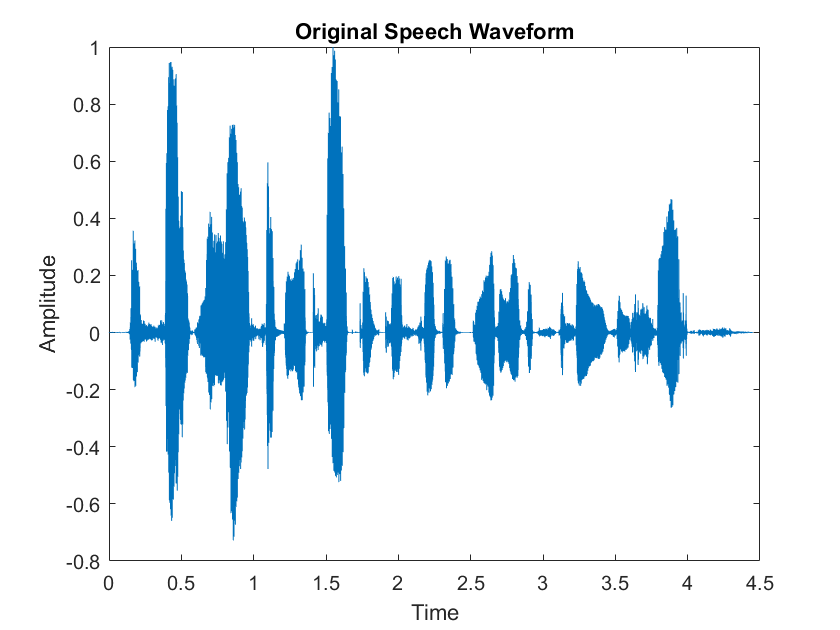

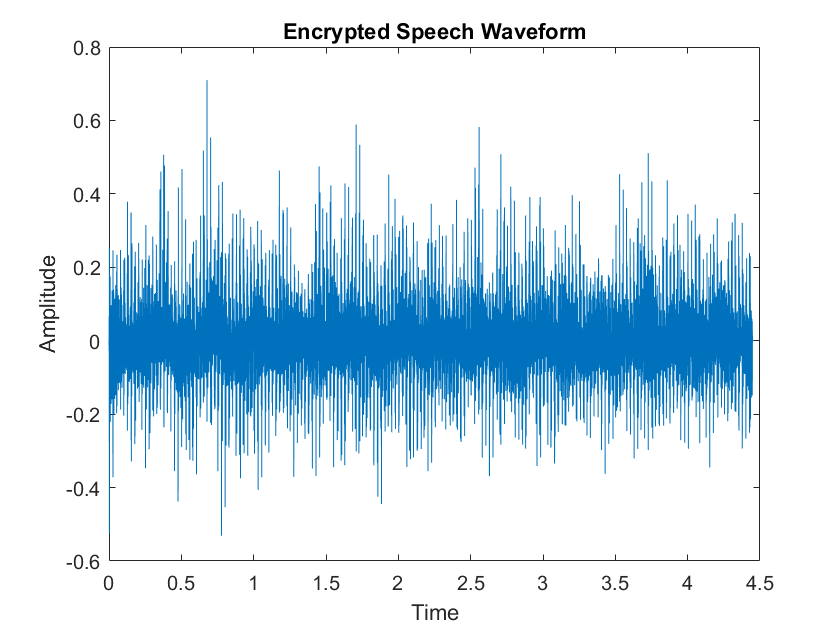

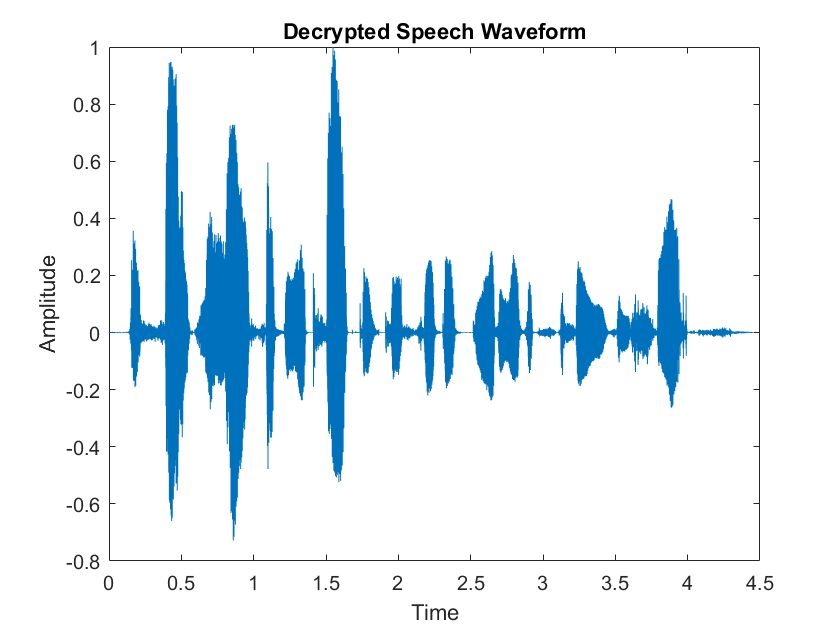

audio sample number : 6

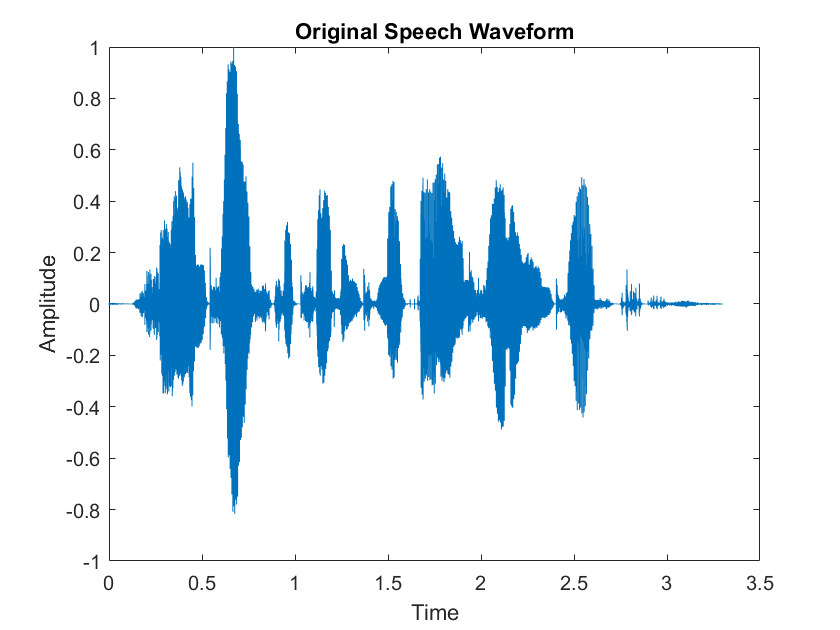

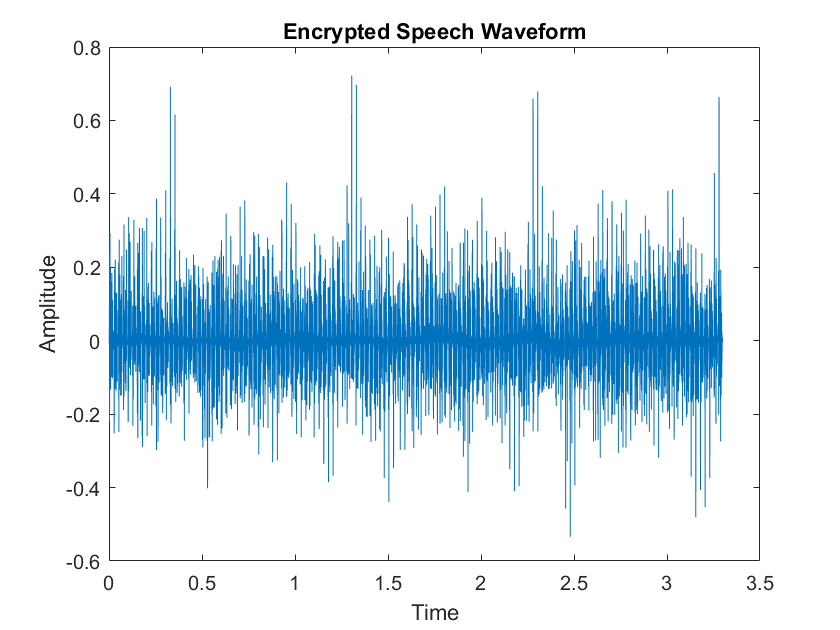

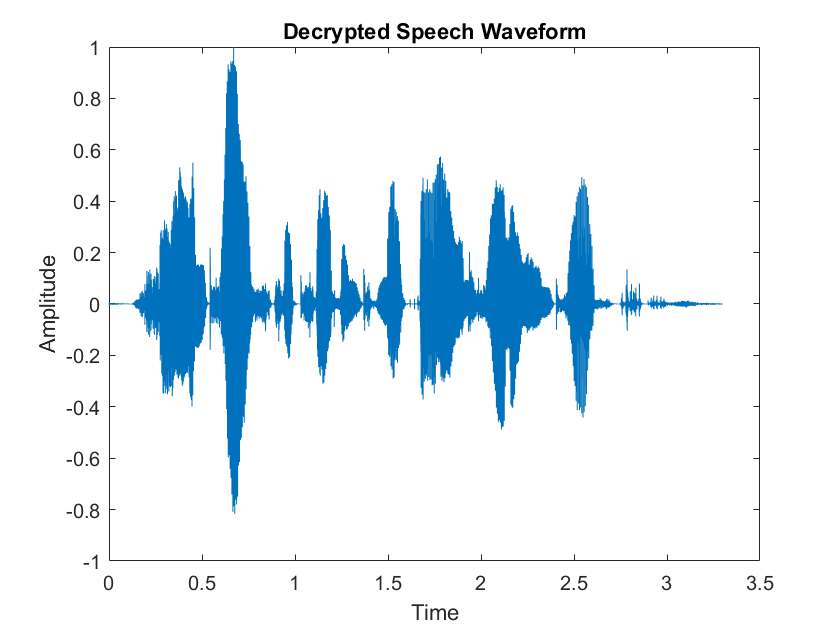

audio sample number : 7

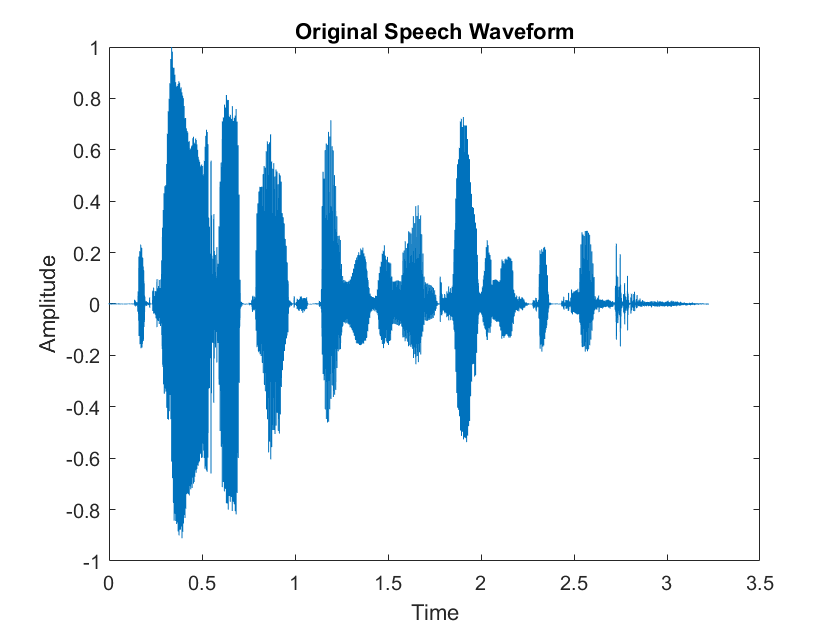

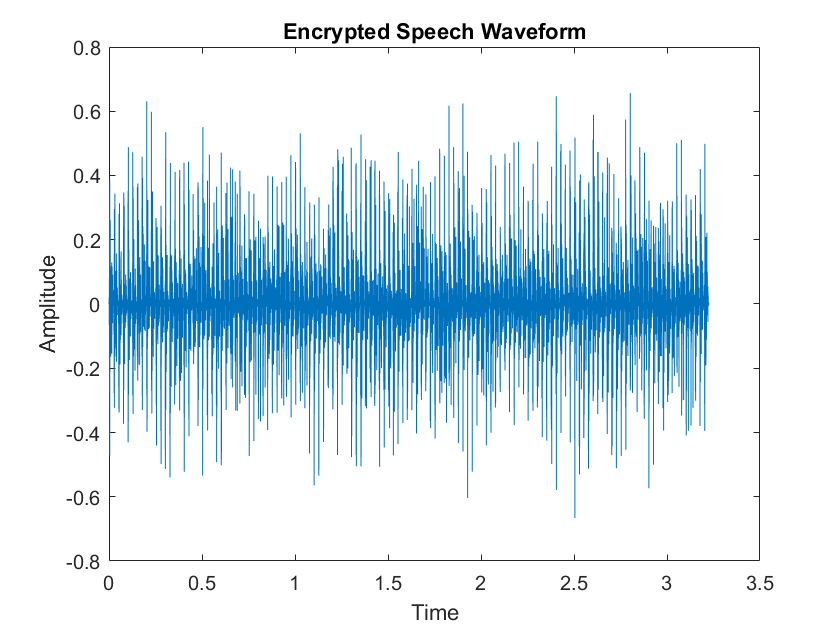

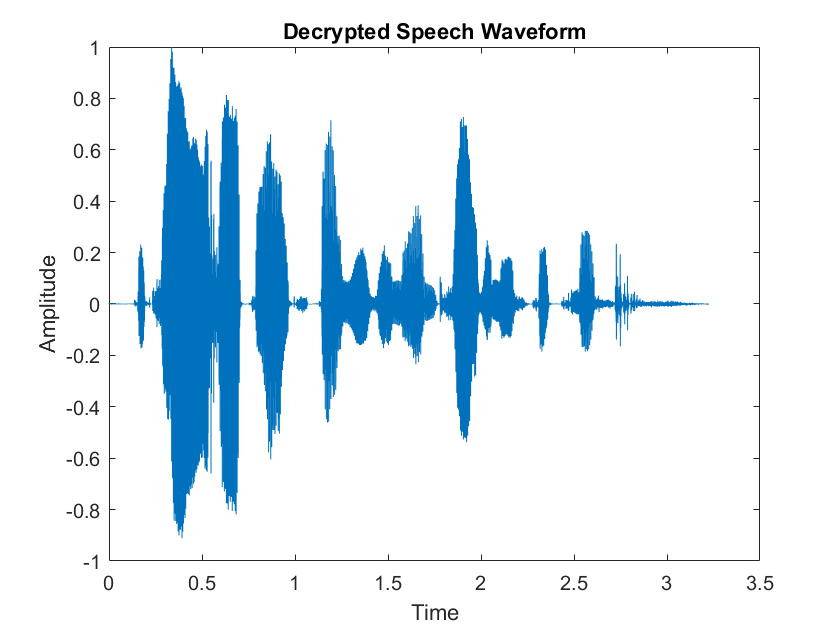

audio sample number : 8

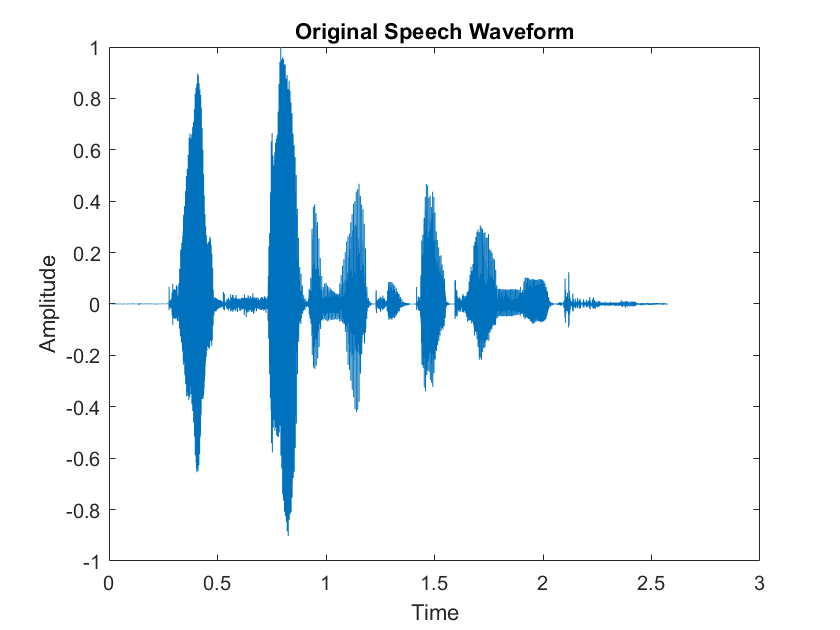

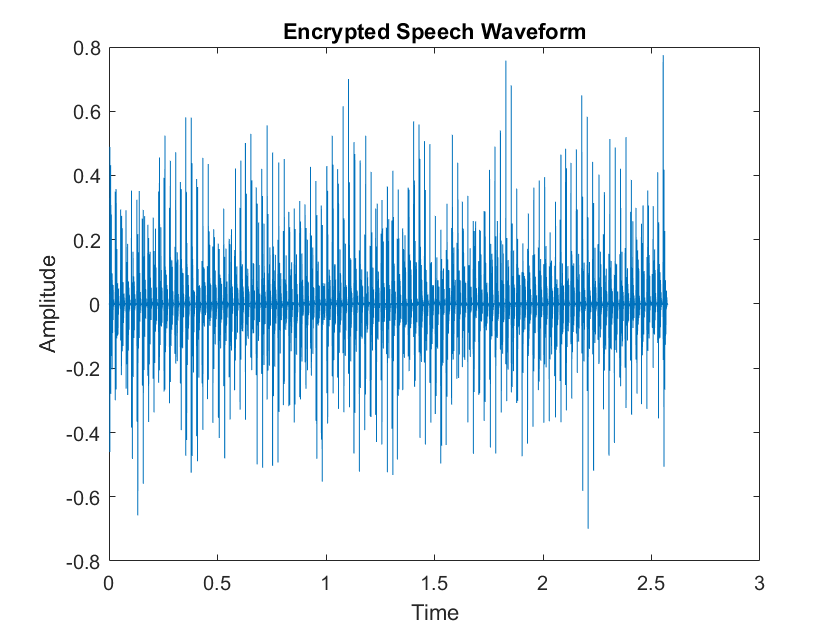

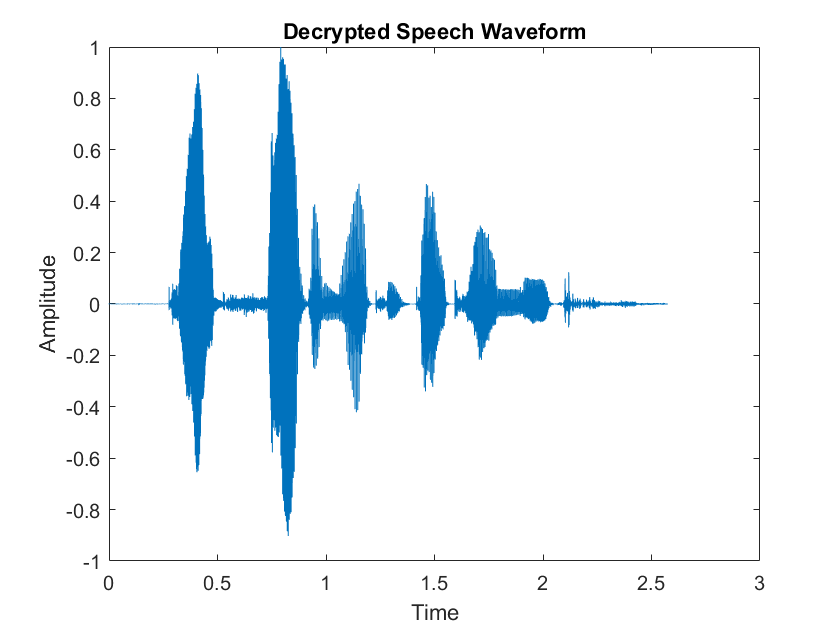

audio sample number : 9

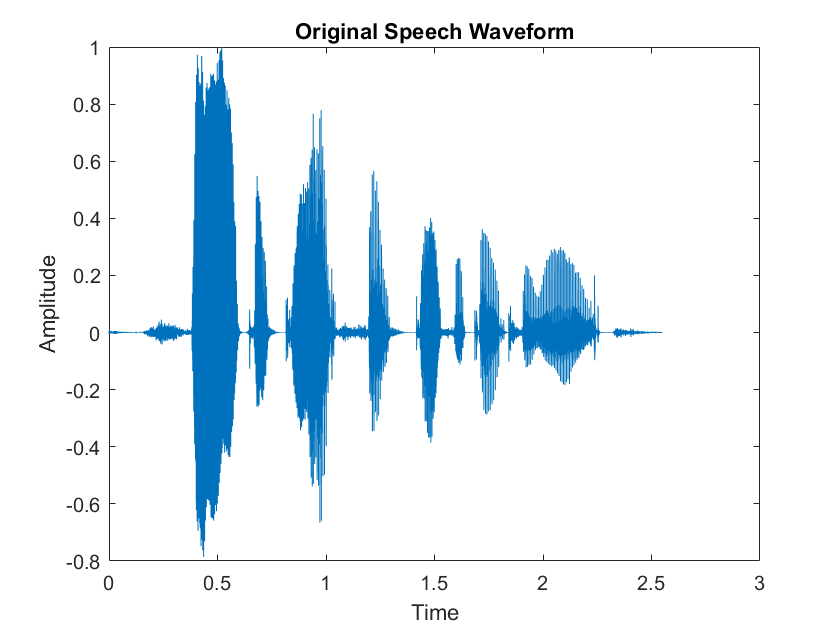

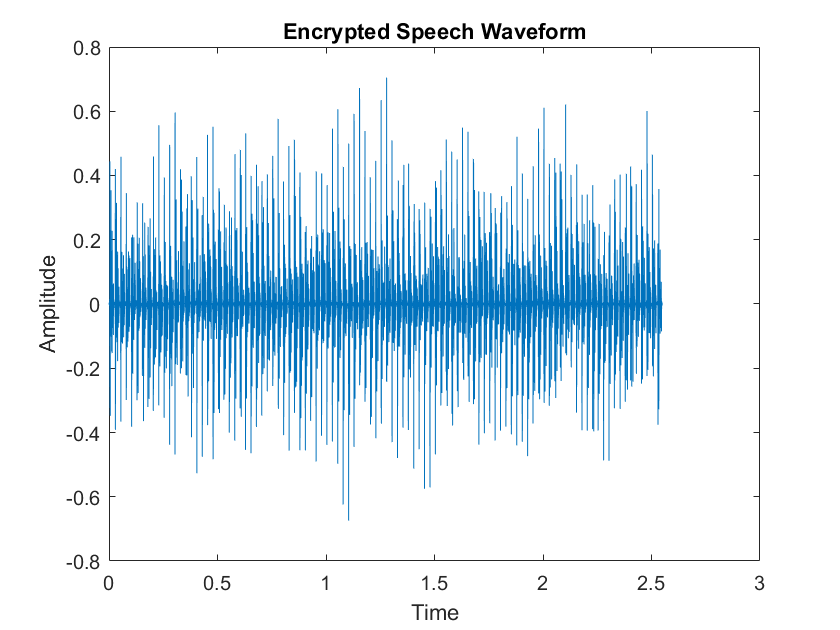

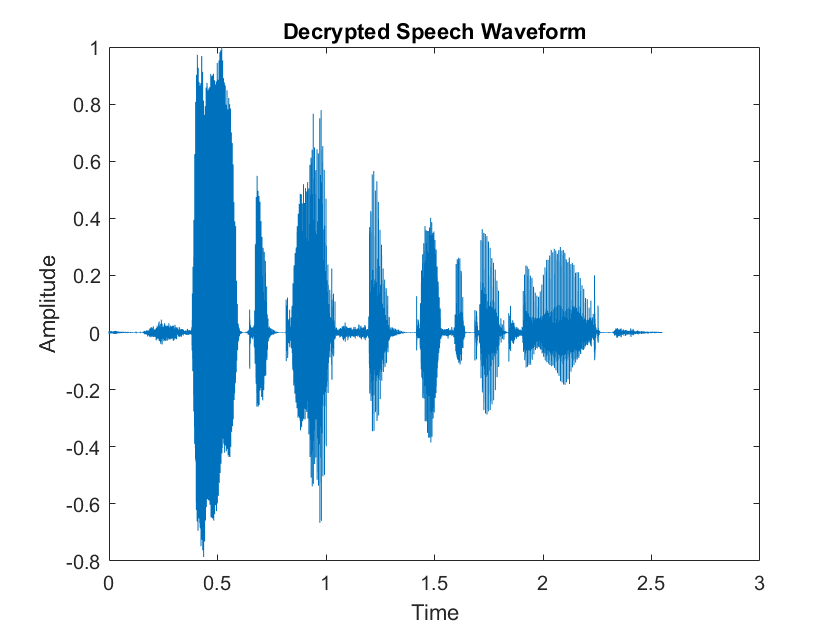

audio sample number : 10

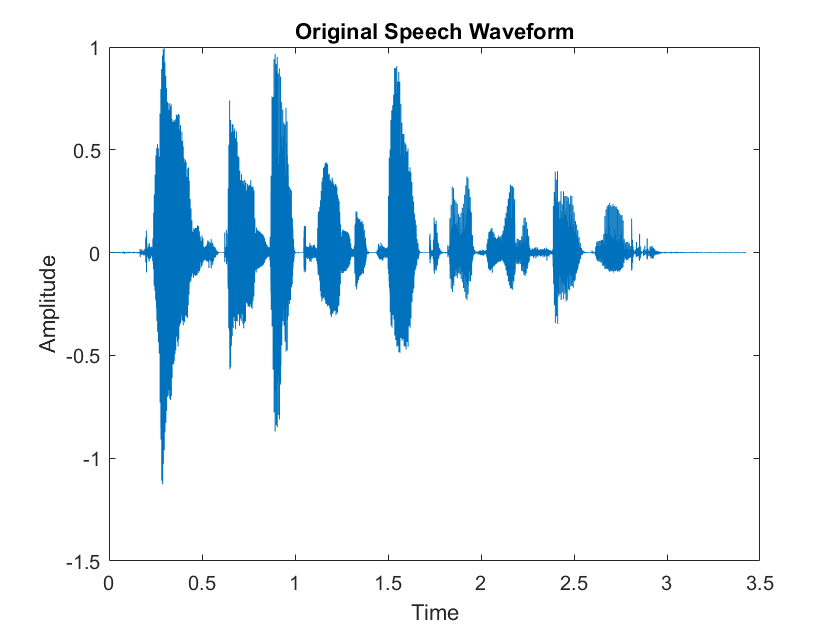

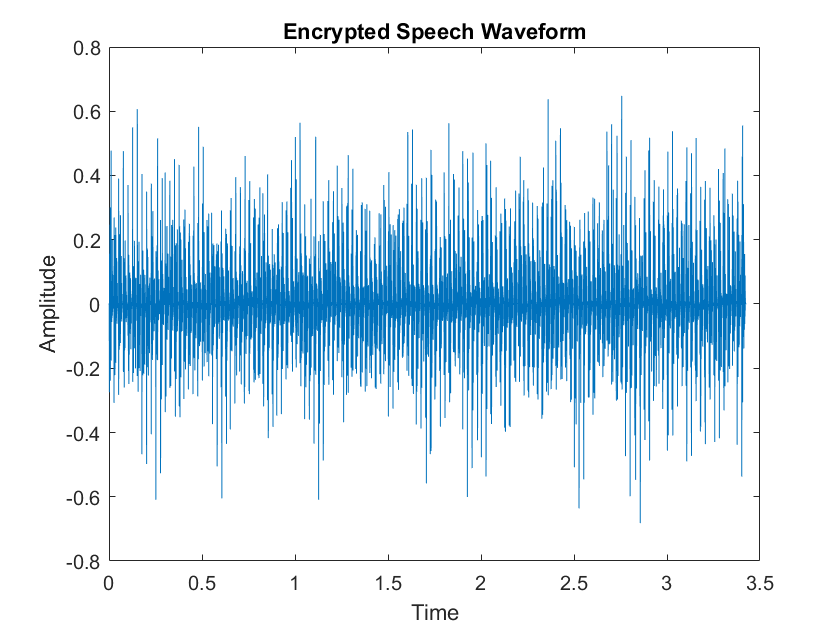

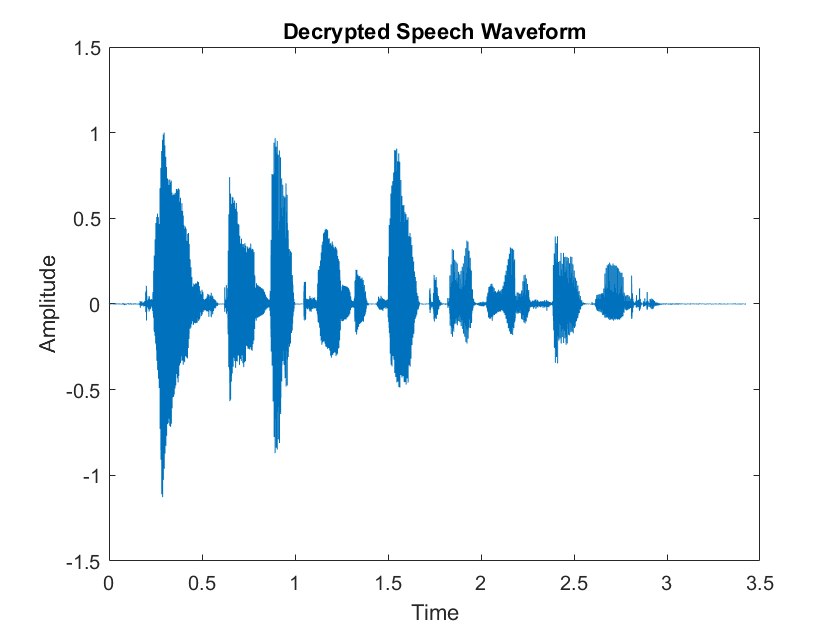

for i = 1:length(waves)
    [sample_sound,fs]=audioread(waves{i}); 
    fprintf('audio sample number : %d', i);
    sample_sound = sample_sound./max(sample_sound);
    
    frame_size = 0.025;
    frame_length = frame_size*fs;
    
    if mod(length(sample_sound), frame_length) ~= 0
        sample_sound = [sample_sound; (zeros(1, frame_length-mod(length(sample_sound), 200)))'];
    end

    figure
    plot((0:length(sample_sound)-1)/fs,sample_sound);  
    xlabel("Time");
    ylabel("Amplitude");
    title('Original Speech Waveform');
    sound(sample_sound, fs);
    pause(5);
    
    [Encrypted_speech, Chaotic_map] = encryption(sample_sound, frame_length);
    
    figure
    plot((0:length(Encrypted_speech)-1)/fs,Encrypted_speech);
    xlabel("Time");
    ylabel("Amplitude");
    title('Encrypted Speech Waveform');
    sound(Encrypted_speech, fs);
    pause(5);
    
    [Decrypted_speech] = decryption(Encrypted_speech, Chaotic_map, frame_length);
    
    figure
    plot((0:length(Decrypted_speech)-1)/fs,Decrypted_speech);
    xlabel("Time");
    ylabel("Amplitude");
    title('Decrypted Speech Waveform');
    sound(Decrypted_speech, fs);
    pause(5);
end

## **FUNCTION DEFINITIONS**

### **ENCRYPTION:**

function [Encrypted_speech_1D, Chaotic_map] = encryption(sample_sound, frame_length)

**       FRAME AND CONVERT TO 2D**

    frames_matrix = reshape(sample_sound, (length(sample_sound)/frame_length), frame_length);

**        DCT**

    frames_dct = dct(frames_matrix); 
    
    Transformed_frames = frames_dct;

**        CHAOTIC MAPPING**

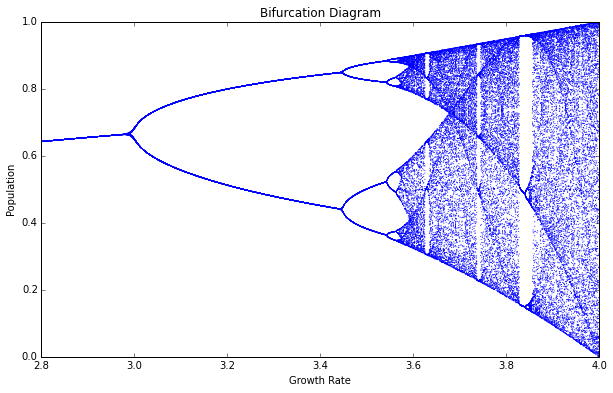

    x1 = 0.1;
    r = 4;
    
    for k = 1: size(frames_matrix, 1)
        for j = 1:size(frames_matrix, 2)
            Chaotic_map(k, j) = r*x1*(1-x1);
            x1 = Chaotic_map(k, j);
        end
    end
    
    Randomized_matrix = Transformed_frames.*Chaotic_map;

**        IDCT**

    Encrypted_speech_2D = idct(Randomized_matrix);

**        CONVERT TO 1-D**

    Encrypted_speech_1D = reshape(Encrypted_speech_2D',[],1); % convert matrix to column vector
end

### **DECRYPTION**

function [Original_1D_matrix] = decryption(Encrypted_speech_1D, Chaotic_map, frame_length)

**        FRAME AND CONVERT TO 2D**

    Received_speech_2D = reshape(Encrypted_speech_1D, frame_length, (length(Encrypted_speech_1D)/frame_length));
    Received_speech_2D = Received_speech_2D';

**        DCT**

    Transformed_Encrypted_speech_2D = dct(Received_speech_2D);

**        INVERSE CHAOTIC MAPPING**

    Unrandomized_matrix = Transformed_Encrypted_speech_2D./Chaotic_map;

**        IDCT**

    Original_2D_matrix = idct(Unrandomized_matrix);

**        CONVERT TO 1-D**

    Original_1D_matrix = reshape(Original_2D_matrix,[],1);
end